# Dictionaries

#### What?

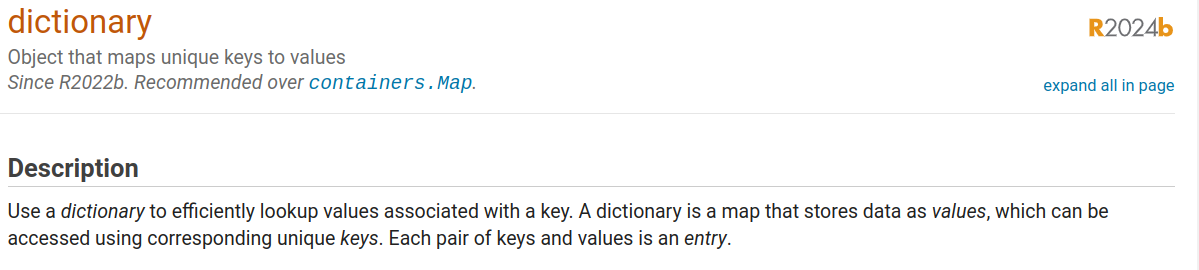

Think of dictionaries as a generalization of an "array" where the index (the dictionary key) can be almost anything and the corresponding element (value) can also be almost anything.

#### Why?

- A powerful, general-perpose abstraction that will provide a structure for problem-solving without needing to write custom objects. (We'll see how this applies to AI/ML.)

- Can improve readability by providing explicit semantic meaning, e.g.,     `settings("maxspeed") = 10.0`

## Creating Dictionaries

Create a dictionary with keys as names (strings)  and values as scores (doubles).   A few options...

scores = dictionary(["Alice", "Bob", "Charlie"], [95, 87, 78])


scores =

  dictionary (string ⟼ double) with 3 entries:

    "Alice"   ⟼ 95
    "Bob"     ⟼ 87
    "Charlie" ⟼ 78



scores = dictionary("Alice", 95, "Bob", 87, "Charlie", 78)


scores =

  dictionary (string ⟼ double) with 3 entries:

    "Alice"   ⟼ 95
    "Bob"     ⟼ 87
    "Charlie" ⟼ 78



scores = dictionary()


scores =

  dictionary with unset key and value types.



scores("Alice") = 95;
scores("Bob") = 87;
scores("Charlie") = 78


scores =

  dictionary (string ⟼ double) with 3 entries:

    "Alice"   ⟼ 95
    "Bob"     ⟼ 87
    "Charlie" ⟼ 78



## Accessing Values (by key)

scores("Bob")

ans = 87

scores(["Bob", "Charlie"])

ans =     87    78


Note case of `isKey`

isKey(scores,"Bob")

ans = logical
   1


isKey(scores,"Deb")

ans = logical
   0


All the values

values(scores)

ans =     95
    87
    78


## Accessing Keys

keys(scores)

ans = 3×1 string array
    "Alice"
    "Bob"
    "Charlie"


scores(keys(scores))

ans =     95
    87
    78


## Modifying exisgint key-value pair

scores('Charlie') = 85


scores =

  dictionary (string ⟼ double) with 3 entries:

    "Alice"   ⟼ 95
    "Bob"     ⟼ 87
    "Charlie" ⟼ 85



## Exercise

Invert the `scores` dictionary as a new dictionary `students` where the numeric values are the keys and the name strings are the values

students = dictionary(values(scores), keys(scores))


students =

  dictionary (double ⟼ string) with 3 entries:

    95 ⟼ "Alice"
    87 ⟼ "Bob"
    85 ⟼ "Charlie"



## Exercise

**Create** a dictionary named `robotConfig` with the following initial settings:

- `'maxSpeed'`: **2.5** (m/s)

- `'minSpeed'`: **0.1** (m/s)

- `'batteryCapacity'`: **5000** (mAh)

**Access** the current `minSpeed` and print its value.

**Add** a new setting, `'maxLoad'`, with a value of **10** (kg).

**Update** the `'batteryCapacity'` to **6000** mAh, as a new battery has been installed.

**Check** if the key `'cameraResolution'` exists in the dictionary. If it does not, add it with a value of `720` (p).

## Using arrays as keys

Consider storing the results of our missile guidance optimizaiton problem.  Recall that for each run we had values for the guidance parameters (N and B) and a corresponding time cost

To use an array as a key, we need to store it as a single element cell array:

performance = dictionary();
performance({[1, 100]}) = 35.1;
performance({[10, 100]}) = 51.2;
performance({[1, 0]}) = 29.0


performance =

  dictionary (cell ⟼ double) with 3 entries:

    {[1 100]}  ⟼ 35.1000
    {[10 100]} ⟼ 51.2000
    {[1 0]}    ⟼ 29



Then we can retrieve our performance for a specific experiment:

N = 10;
B = 100;
cost = performance({[N, B]})

cost = 51.2000

Similarly, if we want to store arrays as values, we need to store them as a cell array:

performance = dictionary();
performance({[1, 100]}) = {[35.1, 10]};
performance({[10, 100]}) = {[51.2, 8.6]};
performance({[1, 0]}) = {[29.0, 11.2]}


performance =

  dictionary (cell ⟼ cell) with 3 entries:

    {[1 100]}  ⟼ {[35.1000 10]}
    {[10 100]} ⟼ {[51.2000 8.6000]}
    {[1 0]}    ⟼ {[29 11.2000]}




N = 10;
B = 100;
cost = performance({[N, B]})

cost = 1×1 cell array
    {[51.2000 8.6000]}


t_cost = cost{1}(1)

t_cost = 51.2000

e_cost = cost{1}(2)

e_cost = 8.6000

## Exercise Example: Store and Retrieve Trajectory Data

Suppose you are working on a robot navigation problem where you want to store the planned trajectory (an array of points) as keys, with each trajectory associated with a corresponding success rate.

Create a custom dictionary where keys are arrays representing robot trajectories, and values are their success rates (percentages).

Store the following entries:

- [1, 2, 3]: 85%

- [4, 5, 6]: 90%

- [7, 8, 9]: 78%

Retrieve and print the success rate for the trajectory [4, 5, 6].

Add a new trajectory [10, 11, 12] with a success rate of 95%.

Check if the trajectory [1, 2, 3] exists and print its success rate.